**Author: Clara Vetter**

**Last modified: 25.01.2024**

addpath(genpath("/Users/claravetter/local/Code/NeuroMiner/NeuroMiner_Current"))
addpath("~/local/Code/mbSPLS/ScrFun_CV/")

# Test script for generalized spls with simulated data - small example

## Simulated data

rng(42);

% Number of samples and features
numSamples = 10;
numFeaturesX = 15;
numFeaturesY = 20;
numFeaturesZ = 10;

% Generate random data matrices X, Y, Z
X = randn(numSamples, numFeaturesX);
Y = randn(numSamples, numFeaturesY);
Z = randn(numSamples, numFeaturesZ);

## Define sPLS parameters

% Sparsity regularization parameters
cu = 3;
cv = 4;
cw = 2;

% Convergence threshold and iteration limit
e = 1e-5;
itr_lim = 1000;

## cv_generalized_spls

matrices{1} = X;
matrices{2} = Y;
matrices{3} = Z;


cs = [cu, cv, cw];
num_matrices = 3;
% Design matrix to model relationship between matrices: Equal influence between matrices 
gs = (1/(num_matrices-1)) * (ones(num_matrices) - eye(num_matrices));

% Run generalized SPLS
[weights, covariances,success] = cv_generalized_spls(matrices, cs, gs, e, itr_lim, 0);

gs

gs =          0    0.5000    0.5000
    0.5000         0    0.5000
    0.5000    0.5000         0


## Hyperopt

- Q: what is the optimisation criterion in this case? How can we define which multi weight vectors maximize covariance in the case that n matrices > 2

% define range of cu, cv, cw for grid search 
cu_range = 1:1:sqrt(size(matrices{1},2));
cv_range = 1:1:sqrt(size(matrices{2},2));
cw_range = 1:1:sqrt(size(matrices{3},2));

% run grid search 
combi_idx_xyz = 0;
combi_idx_xy = 0;
result_table_xyz_gspls = array2table(zeros(length(cu_range)*length(cv_range)*length(cw_range),11), 'VariableNames',{'cu', 'cv', 'cw', 'corr_XY', 'corr_XZ', 'corr_YZ', 'spls_itr', 'diff', 'dim_m1', 'dim_m2', 'dim_m3'});
result_table_xy_spls = array2table(zeros(length(cu_range)*length(cv_range),7), 'VariableNames',{'cu', 'cv', 'corr_XY', 'spls_itr', 'diff', 'dim_m1', 'dim_m2'});
results_xyz = struct();
for i=1:length(cu_range)
    for j=1:length(cv_range)
        for k=1:length(cw_range)
            cu = cu_range(i);
            cv = cv_range(j);
            cw = cw_range(k);
            combi_idx_xyz = combi_idx_xyz+1;
            cs = [cu, cv, cw];
            % Run generalized SPLS
            [weights, covariances, success, spls_itr, diff, dim_Ms] = cv_generalized_spls(matrices, cs, gs, e, itr_lim, 0);
            corr_XY = corr(matrices{1}*weights{1},matrices{2}*weights{2});
            corr_XZ = corr(matrices{1}*weights{1},matrices{3}*weights{3});
            corr_YZ = corr(matrices{2}*weights{2},matrices{3}*weights{3});
            result_table_xyz_gspls.cu(combi_idx_xyz) = cu; 
            result_table_xyz_gspls.cv(combi_idx_xyz) = cv; 
            result_table_xyz_gspls.cw(combi_idx_xyz) = cw; 
            result_table_xyz_gspls.corr_XY(combi_idx_xyz) = corr_XY;
            result_table_xyz_gspls.corr_XZ(combi_idx_xyz) = corr_XZ;
            result_table_xyz_gspls.corr_YZ(combi_idx_xyz) = corr_YZ;
            result_table_xyz_gspls.spls_itr(combi_idx_xyz) = spls_itr; 
            result_table_xyz_gspls.diff(combi_idx_xyz) = diff; 
            result_table_xyz_gspls.dim_m1(combi_idx_xyz) = dim_Ms(1);
            result_table_xyz_gspls.dim_m2(combi_idx_xyz) = dim_Ms(2);
            result_table_xyz_gspls.dim_m3(combi_idx_xyz) = dim_Ms(3);

            results_xyz.cu{combi_idx_xyz}  = cu; 
            results_xyz.cv{combi_idx_xyz}  = cv; 
            results_xyz.cw{combi_idx_xyz}  = cw; 
            results_xyz.weights{combi_idx_xyz} = weights; 
            
        end
        combi_idx_xy = combi_idx_xy+1;
        [u, v, success, spls_itr, diff, dim_Ms] = cv_spls(Y, Z, cv, cw, e, itr_lim, 0); 
        corr_XY = corr(Y*u, Z*v); 
        result_table_xy_spls.cu(combi_idx_xy) = cu; 
        result_table_xy_spls.cv(combi_idx_xy) = cv;
        result_table_xy_spls.corr_XY(combi_idx_xy) = corr_XY;
        result_table_xy_spls.spls_itr(combi_idx_xy) = spls_itr;
        result_table_xy_spls.diff(combi_idx_xy) = diff;
        result_table_xy_spls.dim_m1(combi_idx_xy) = dim_Ms(1);
        result_table_xy_spls.dim_m2(combi_idx_xy) = dim_Ms(2);
    end
end

SPLS: itr: 2    diff: 0.00e+00    dim_M1: 1    dim_M2: 1    dim_M3: 1    


SPLS: itr: 1001    diff: 2.89e-01    dim_M1: 1    dim_M2: 1    dim_M3: 10    


SPLS: itr: 1001    diff: 6.01e-01    dim_M1: 1    dim_M2: 1    dim_M3: 10    


SPLS: itr: 2    diff: 0.00e+00    dim_u: 1    dim_v: 10


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 1    dim_M2: 7    dim_M3: 1    
SPLS: itr: 2    diff: 0.00e+00    dim_M1: 1    dim_M2: 6    dim_M3: 6    
SPLS: itr: 2    diff: 0.00e+00    dim_M1: 1    dim_M2: 6    dim_M3: 10    


SPLS: itr: 17    diff: 6.24e-06    dim_u: 11    dim_v: 10


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 1    dim_M2: 14    dim_M3: 1    
SPLS: itr: 2    diff: 0.00e+00    dim_M1: 1    dim_M2: 13    dim_M3: 6    
SPLS: itr: 2    diff: 0.00e+00    dim_M1: 1    dim_M2: 14    dim_M3: 10    


SPLS: itr: 9    diff: 6.80e-06    dim_u: 17    dim_v: 10


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 1    dim_M2: 20    dim_M3: 1    
SPLS: itr: 2    diff: 0.00e+00    dim_M1: 1    dim_M2: 20    dim_M3: 6    
SPLS: itr: 2    diff: 0.00e+00    dim_M1: 1    dim_M2: 20    dim_M3: 10    


SPLS: itr: 1    diff: 5.95e-16    dim_u: 20    dim_v: 10


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 9    dim_M2: 1    dim_M3: 1    


SPLS: itr: 1001    diff: 2.01e-01    dim_M1: 7    dim_M2: 1    dim_M3: 6    


SPLS: itr: 1001    diff: 2.51e-01    dim_M1: 7    dim_M2: 1    dim_M3: 10    


SPLS: itr: 2    diff: 0.00e+00    dim_u: 1    dim_v: 10


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 8    dim_M2: 6    dim_M3: 1    
SPLS: itr: 24    diff: 7.03e-06    dim_M1: 7    dim_M2: 5    dim_M3: 7    
SPLS: itr: 24    diff: 6.03e-06    dim_M1: 6    dim_M2: 5    dim_M3: 10    


SPLS: itr: 17    diff: 6.24e-06    dim_u: 11    dim_v: 10


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 7    dim_M2: 16    dim_M3: 1    
SPLS: itr: 40    diff: 9.36e-06    dim_M1: 8    dim_M2: 14    dim_M3: 7    
SPLS: itr: 42    diff: 9.07e-06    dim_M1: 6    dim_M2: 16    dim_M3: 10    


SPLS: itr: 9    diff: 6.80e-06    dim_u: 17    dim_v: 10


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 7    dim_M2: 20    dim_M3: 1    
SPLS: itr: 44    diff: 9.45e-06    dim_M1: 8    dim_M2: 20    dim_M3: 7    
SPLS: itr: 57    diff: 9.96e-06    dim_M1: 7    dim_M2: 20    dim_M3: 10    


SPLS: itr: 1    diff: 5.95e-16    dim_u: 20    dim_v: 10


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 15    dim_M2: 1    dim_M3: 1    


SPLS: itr: 1001    diff: 4.82e-01    dim_M1: 14    dim_M2: 1    dim_M3: 5    
SPLS: itr: 11    diff: 0.00e+00    dim_M1: 13    dim_M2: 1    dim_M3: 10    


SPLS: itr: 2    diff: 0.00e+00    dim_u: 1    dim_v: 10


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 15    dim_M2: 6    dim_M3: 1    
SPLS: itr: 55    diff: 9.09e-06    dim_M1: 14    dim_M2: 6    dim_M3: 5    
SPLS: itr: 51    diff: 8.27e-06    dim_M1: 14    dim_M2: 6    dim_M3: 10    


SPLS: itr: 17    diff: 6.24e-06    dim_u: 11    dim_v: 10


SPLS: itr: 4    diff: 0.00e+00    dim_M1: 15    dim_M2: 15    dim_M3: 1    
SPLS: itr: 96    diff: 9.66e-06    dim_M1: 14    dim_M2: 15    dim_M3: 6    
SPLS: itr: 61    diff: 8.62e-06    dim_M1: 14    dim_M2: 15    dim_M3: 10    


SPLS: itr: 9    diff: 6.80e-06    dim_u: 17    dim_v: 10


SPLS: itr: 6    diff: 0.00e+00    dim_M1: 15    dim_M2: 20    dim_M3: 1    
SPLS: itr: 98    diff: 9.54e-06    dim_M1: 15    dim_M2: 20    dim_M3: 7    
SPLS: itr: 85    diff: 9.02e-06    dim_M1: 14    dim_M2: 20    dim_M3: 10    


SPLS: itr: 1    diff: 5.95e-16    dim_u: 20    dim_v: 10


## Weight updating pairwise spls vs. gspls

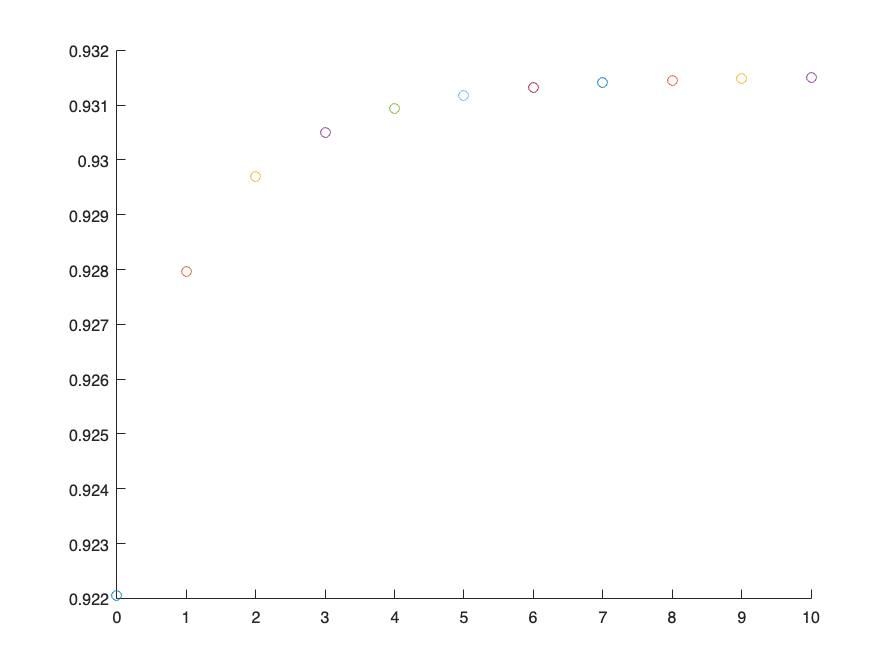

SPLS: itr: 11    diff: 1.30e-04    dim_u: 11    dim_v: 10


cv = 2; 
cw = 4;
[u,v,success,spls_itr, diff, dim_Ms] = cv_spls(Y,Z, cv, cw, e, 10, 1);

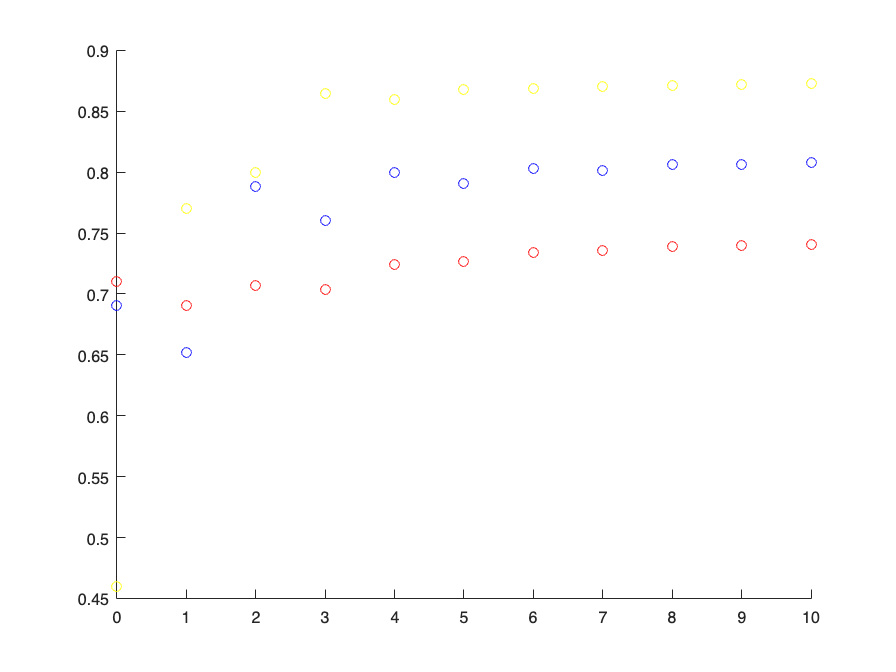

SPLS: itr: 11    diff: 6.02e-03    dim_M1: 6    dim_M2: 20    dim_M3: 10    


% Sparsity regularization parameters
cu = 2;
cv = 4;
cw = 4;
cs = [cu, cv, cw];
[u,v,success,spls_itr, diff, dim_Ms] = cv_generalized_spls(matrices, cs, gs, e, 10, 1);

matrices2{1} = X;
matrices2{2} = Y;
cs2 = [cu, cv];
num_matrices2 = 2;
gs2 = (1/(num_matrices2-1)) * (ones(num_matrices2) - eye(num_matrices2));

% Run generalized SPLS
[weights, covariances,success] = cv_generalized_spls(matrices2, cs2, gs2, e, itr_lim, 0);

SPLS: itr: 60    diff: 9.44e-06    dim_M1: 15    dim_M2: 20    


[u,v,success,spls_itr, diff, dim_Ms] = cv_spls(X,Y, cu, cv, e, itr_lim, 0);

SPLS: itr: 60    diff: 9.84e-06    dim_u: 15    dim_v: 20


weights{1} == u

ans = 15×1 logical array
   0
   0
   0
   1
   0
   1
   0
   0
   0
   0


weights{3}